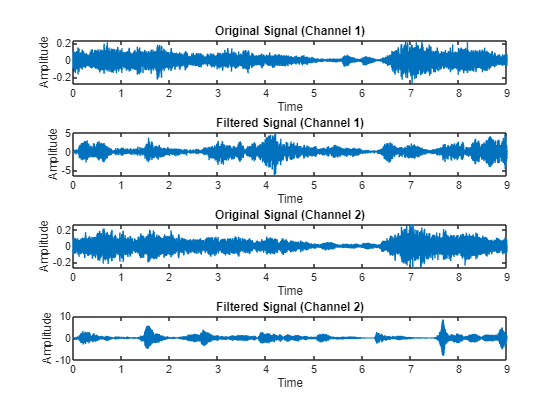

%Load audio file
[data, fs] = audioread('audio.wav');

%Load standard pulse
load('Pulse.mat');

%Perform matched filtering on each channel
filtered_signals = zeros(length(data), size(data, 2));
for i = 1:size(data, 2)
    filtered_signals(:, i) = conv(data(:, i), flipud(yp), 'same');
end

%Define time vector in seconds
t = (0:length(data)-1) / fs;
%normalization
filtered_signals_norm = normalize(filtered_signals);

%Plot original and filtered signals
figure;
subplot(4, 1, 1);
plot(t,data(:, 1)); %original signal for channel 1
title('Original Signal (Channel 1)');
xlabel('Time')
ylabel('Amplitude')
xlim([0,9]);

subplot(4, 1, 3);
plot(t,data(:, 2)); %original signal for channel 2
title('Original Signal (Channel 2)');
xlabel('Time')
ylabel('Amplitude')
xlim([0,9]);

subplot(4, 1, 2);
plot(t,filtered_signals_norm(:, 1)); %filtered signal for channel 1
title('Filtered Signal (Channel 1)');
xlabel('Time')
ylabel('Amplitude')
xlim([0,9]);

subplot(4, 1, 4);
plot(t,filtered_signals_norm(:, 2)); %filtered signal for channel 2
title('Filtered Signal (Channel 2)');
xlabel('Time')
ylabel('Amplitude')
xlim([0,9]);